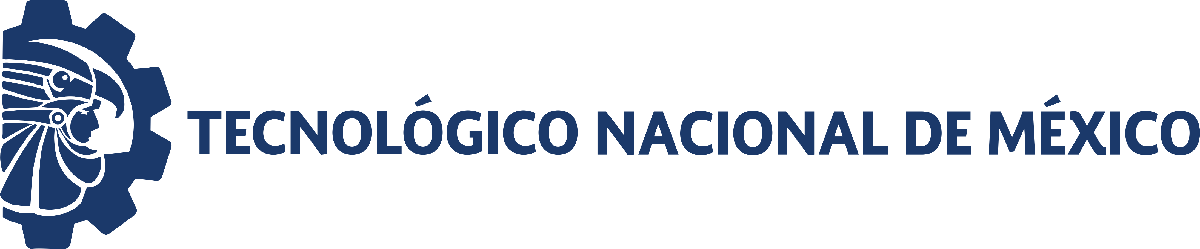                                 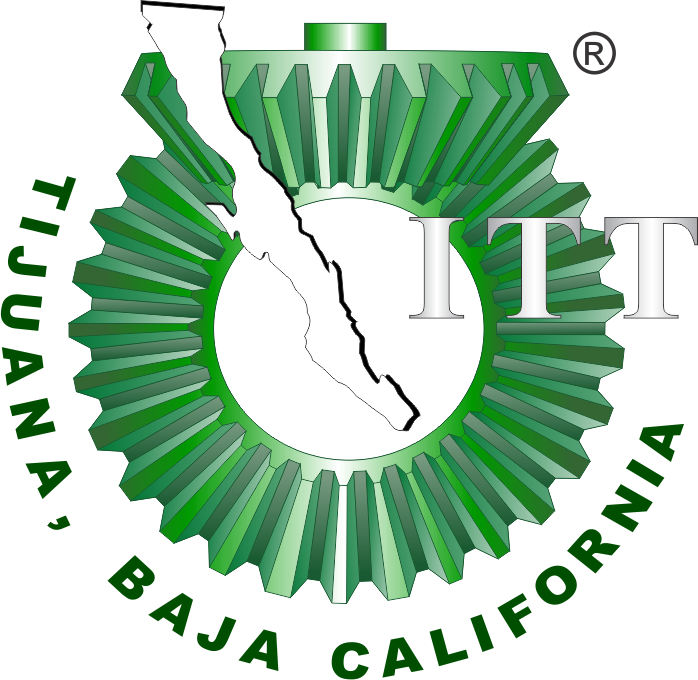

# Práctica 3: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

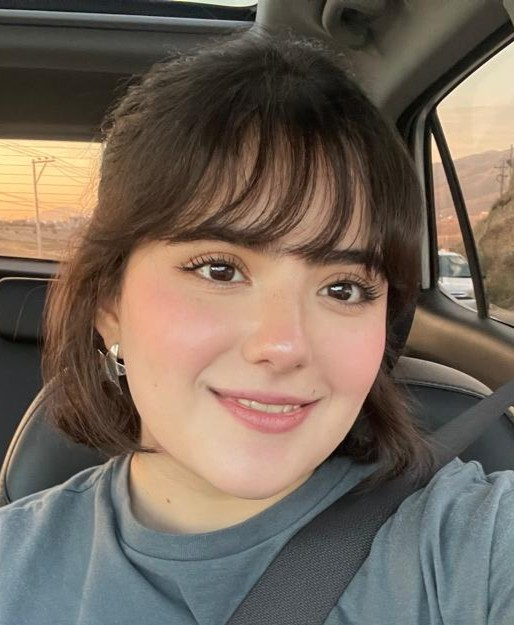

Nombre del alumno: **Nicole Zoe Camacho Quezada**

Número de control: **22211747**

Correo institucional: **L22211747@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

set_param('Sistema3/F(t)', 'Amplitude', '1');
set_param('Sistema3/F(t)', 'Period', '10');
set_param('Sistema3/F(t)', 'PulseWidth', '10');
set_param('Sistema3/F(t)', 'PhaseDelay', '1');


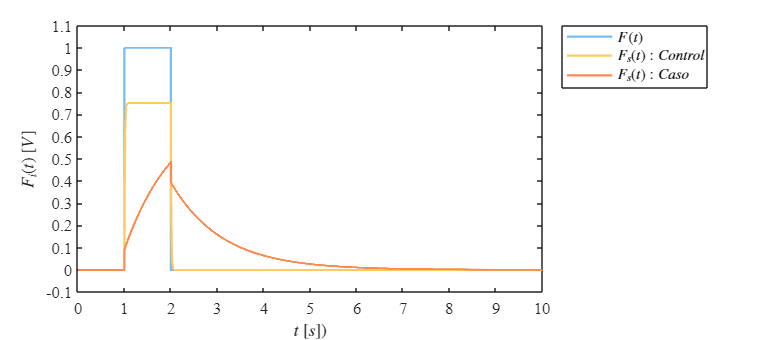

Signal = 'Lazo abierto';
x1 = sim(file, parameters);

plotsignal(x1.t, x1.F, x1.Fs1, x1.Fs2, Signal)

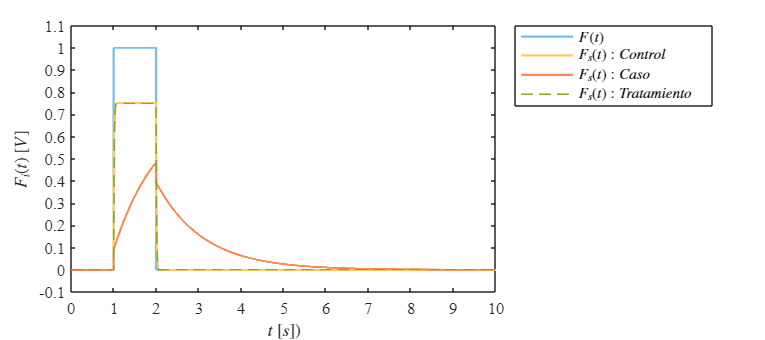

Signal='Lazo cerrado';
x2 = sim(file, parameters);
plotsignals(x2.t, x2.F, x2.Fs1, x2.Fs2, x2.Fs3, Signal)

## Función: Respuesta a las senales

function plotsignal(t, F, Fs1, Fs2, Signal)
    set(figure(),'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    
    mycolors = [119, 190, 240;
                255, 203, 097;
                255, 137, 079;
                138, 166, 036;
                092, 047, 194; 
                234, 91, 111]/255;
    colororder(mycolors)

    plot(t, F, '-', t, Fs1, '-', t, Fs2, '-',...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
 
    L = legend('$F(t)$', '$F_s(t) : Control$', '$F_s(t) : Caso$');
    set(L, 'Interpreter', 'Latex','FontSize',10,'Location','BestOutside', 'Box','On');
            
    
    xlabel('$t$ $[s]$)', 'Interpreter', 'Latex ', 'Fontsize', 11)
    ylabel('$F_i(t)$ $[V]$', 'Interpreter', 'Latex ', 'Fontsize', 11)
    
 
    xlim([0,10]); xticks(0:1:10)
    if Signal=="Lazo abierto"
        ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1)
    end

    exportgraphics(gcf,[Signal,'.pdf'], 'ContentType', 'Vector')
    exportgraphics(gcf,[Signal,'.png'], 'ContentType', 'Vector')
end

function plotsignals(t, F, Fs1, Fs2, Fs3, Signal)
    set(figure(),'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    
    mycolors = [119, 190, 240;
                255, 203, 097;
                255, 137, 079;
                138, 166, 036;
                092, 047, 194; 
                234, 91, 111]/255;
    colororder(mycolors)

    p = plot(t, F, '-', t, Fs1, '-', t, Fs2, '-', t, Fs3, '--',...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
        set(p(4), 'LineWidth', 1); set(p(4), 'LineWidth', 1);
    L = legend('$F(t)$', '$F_s(t) : Control$', '$F_s(t) : Caso$', '$F_s(t) : Tratamiento$');
    set(L, 'Interpreter', 'Latex','FontSize',10,'Location','BestOutside', 'Box','On');
            
    
    xlabel('$t$ $[s]$)', 'Interpreter', 'Latex ', 'Fontsize', 11)
    ylabel('$F_i(t)$ $[V]$', 'Interpreter', 'Latex ', 'Fontsize', 11)
    
 
    xlim([0,10]); xticks(0:1:10)
    if Signal=="Lazo cerrado"
        ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1)
    end
    exportgraphics(gcf,[Signal,'.pdf'], 'ContentType', 'Vector')
    exportgraphics(gcf,[Signal,'.png'], 'ContentType', 'Vector')
end

